# Построение графиков

## Построение

Выполним подготовительные действия для построения графика синуса.

f = 1000;               % Зададим частоту
X = [0:0.00001:0.002];  % Определим временную ось
Y = sin(2*pi*f*X);      % Посчитаем значения функции

Построим график.

plot(X, Y);

Добавим подписи на график.

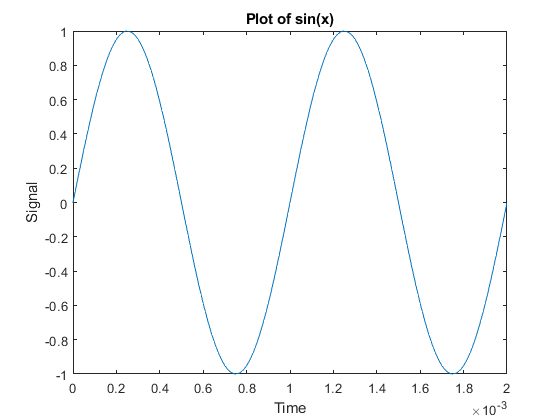

title('Plot of sin(x)');    % Название
xlabel('Time');             % Горизонтальная ось
ylabel('Signal');           % Вертикальная ось

Функция `plot` позволяет построить несколько зависимостей на одном графике.

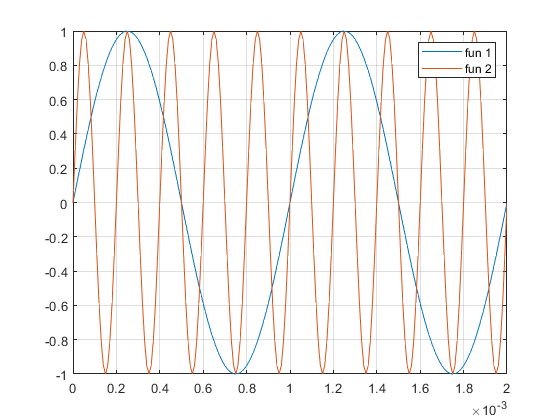

% Зададим вторую функцию
f2 = 5000;
Y2 = sin(2*pi*f2*X);

plot(X, Y, X, Y2);          % Построим обе функции на одном графике
grid on;                    % Включим сетку
legend('fun 1', 'fun 2');   % Включим легенду

Фукнция `plot` строит график, соединяя точки прямыми линиями. Бывает нужен другой способ построения, например, в виде дискретных вертикальных линий, тогда можно использовать функцию `stem`.

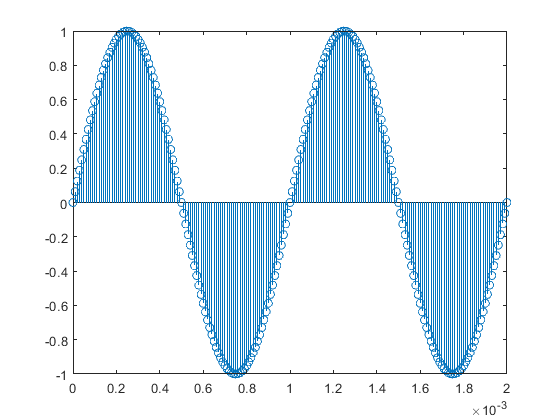

stem(X, Y);

## Совмещение графиков

Снова построим первую функцию

plot(X, Y);

Наложим на этот график вторую функцию, построенную другим способом.

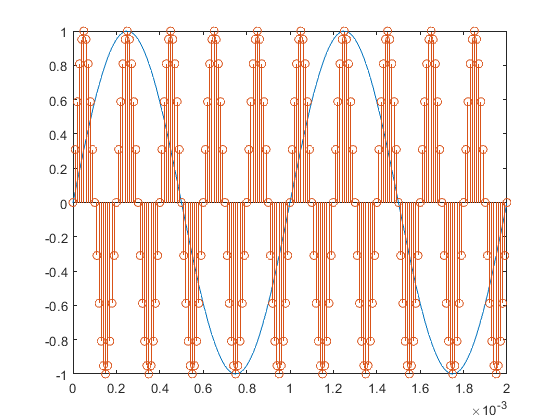

hold on;        % Включаем наложение графиков
stem(X, Y2);
hold off;       % Отключаем наложение графиков